# dayplotter

clearvars -except xxkg xxkg2 hkg hkg2 dark light darkmulti lightmulti darker darkraw multidarkraw rawdark multirawdark %clear variables that aren't giant structures

# single fish

Average amplitude range figure

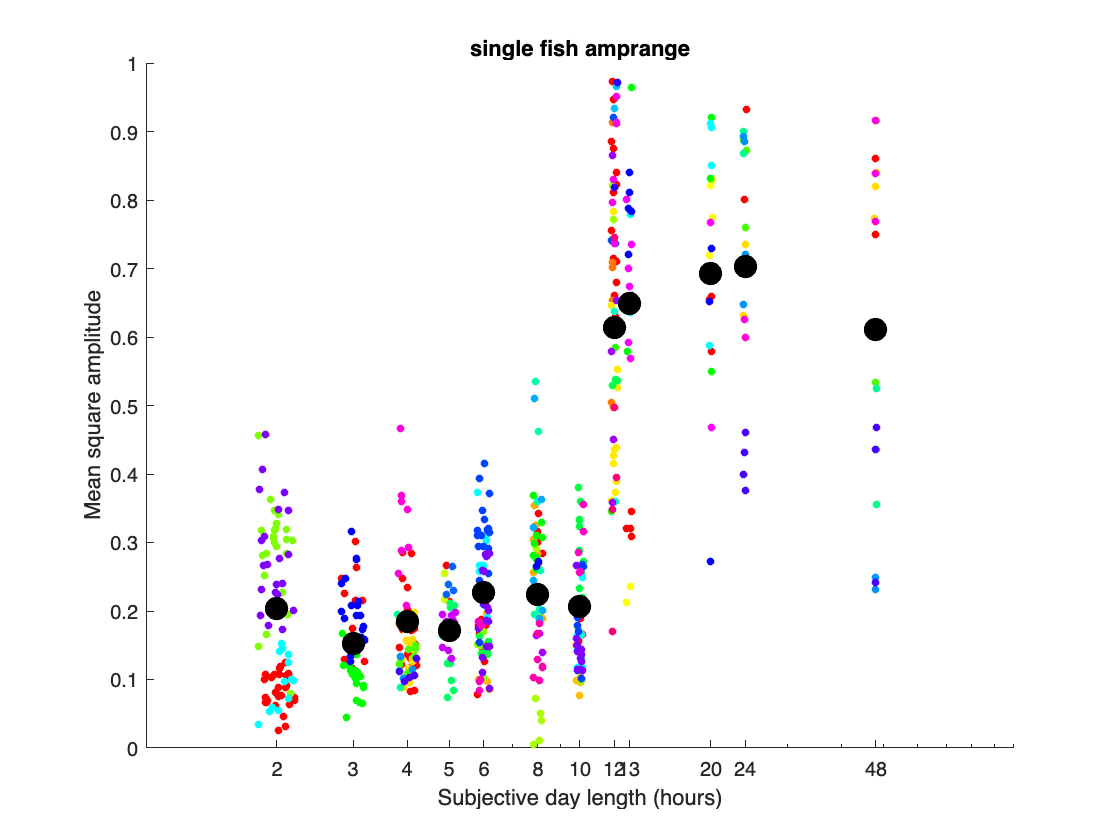

figure(89); clf; title('single fish amprange'); hold on;
 set(gcf, 'renderer', 'painters');
    for j = 1:length(dark)

        ld(j,:) = dark(j).ld;
       
        for kk = 1:length([dark(j).fish])
            clrbyfish = hsv(length(dark(j).fish));
            for jj = 1:length(dark(j).fish(kk).amprange)
            %plot(ld(j,:), dark(j).fish(kk).amprange(jj), '.', 'MarkerSize', 8);
            scatter(ld(j,:), dark(j).fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
            end
        end
       
        plot(ld(j,:), dark(j).exp.expavgrange, 'k.', 'MarkerSize', 35);

    end
   set(gca,'xscale', 'log');%, 'yscale', 'log');
  % ylim([0 2]);
   xticks([2 3 4 5 6 8 10 12 13 20 24 48]);
   xlabel('Subjective day length (hours)');
   ylabel('Mean square amplitude');
   set(gcf, 'renderer', 'painters');

Daymean average

## dark to light

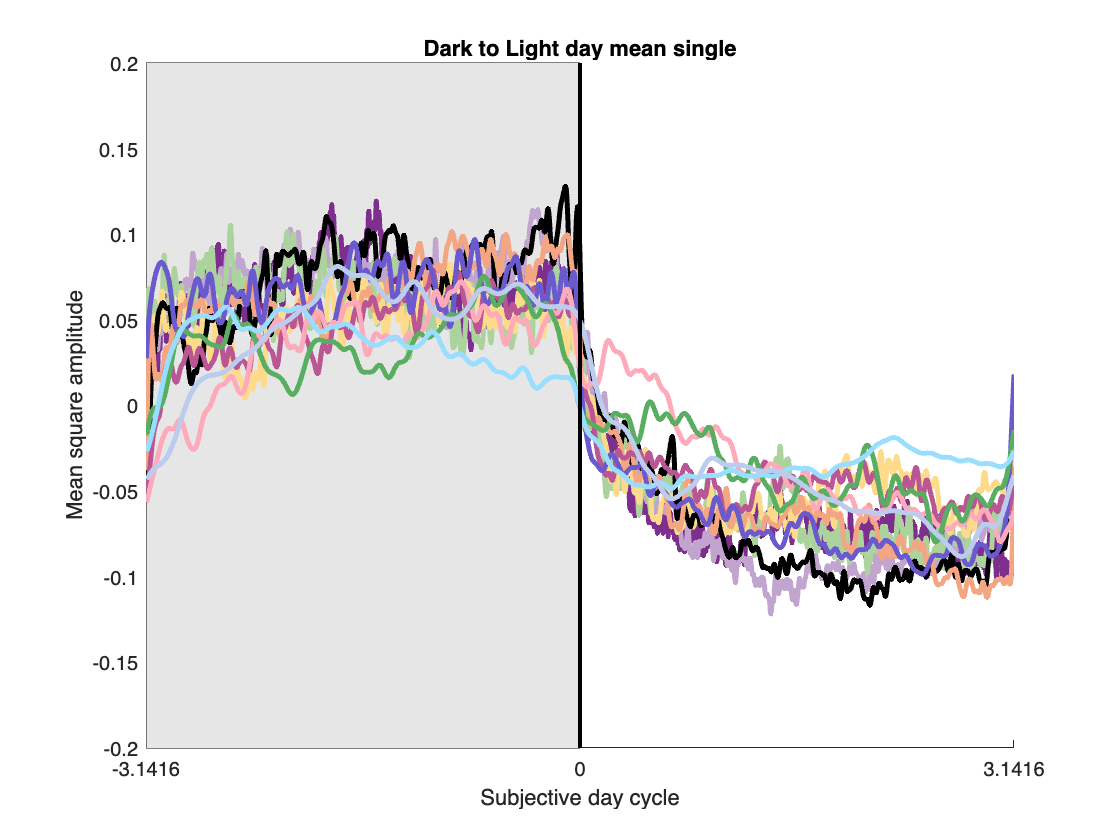

figure(317); clf; title('Dark to Light day mean single'); hold on; 
    
    set(gca,'XTick',-2*pi:pi:2*pi);
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    ylim([-0.2 0.2]);
    xlim([-pi pi]);
   % xlim([-.5 .5]);
    a = ylim;
clrs = k_colormefriendly;

    fill([-pi -pi 0 0], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');

    for j = length(dark):-1:1
   
        ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * dark(j).ld);
        plot((dark(j).exp.hourtim .* crosshour)-pi, dark(j).exp.meanofexperimentmeans-mean(dark(j).exp.meanofexperimentmeans), 'LineWidth', 2.5,'Color', clrs(j,:),'DisplayName',num2str(ld(j)));
        
        % legend(num2str(ld(j))); 
       % legend('AutoUpdate', 'off'); 
     %  legend;
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');

## light to dark

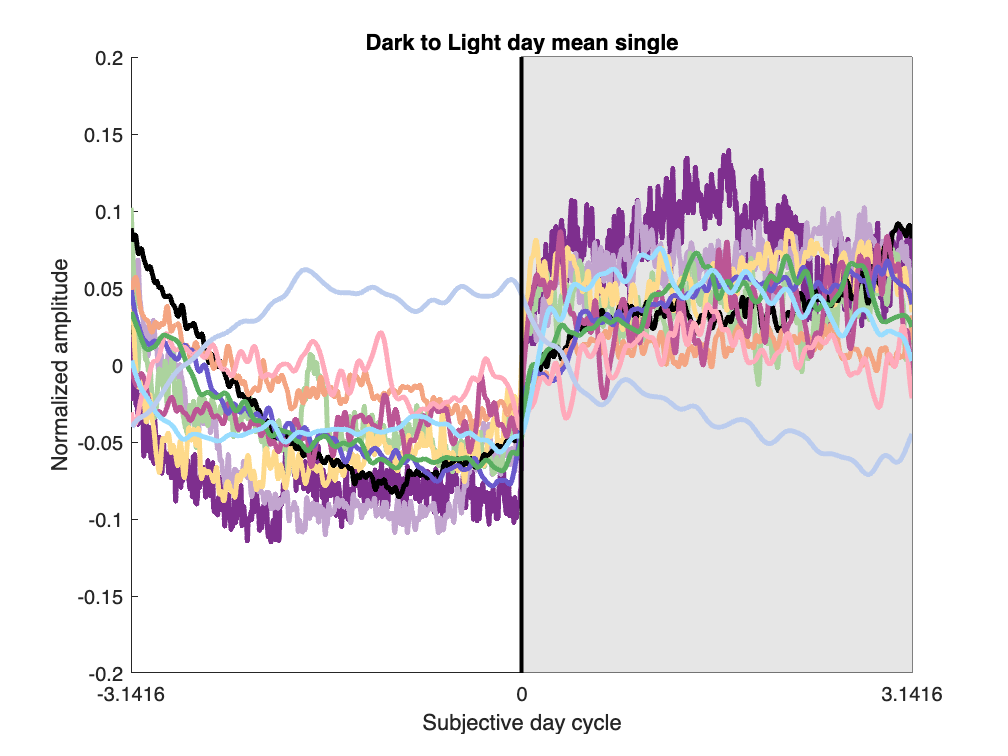

figure(317); clf; title('Dark to Light day mean single'); hold on; 
    
    set(gca,'XTick',-2*pi:pi:2*pi);
     ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    ylim([-0.2 0.2]);
    xlim([-pi pi]);
    %xlim([-.5 .5]);
    a = ylim;
clrs = k_colormefriendly;

    fill([0 0 pi pi], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');

    for j = length(light):-1:1
   
        ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * light(j).ld); 
        plot((light(j).exp.hourtim .* crosshour)-pi, light(j).exp.meanofexperimentmeans-mean(light(j).exp.meanofexperimentmeans), 'LineWidth', 2.5,'Color', clrs(j,:),'DisplayName',num2str(ld(j)));
        
        % legend(num2str(ld(j))); 
       % legend('AutoUpdate', 'off'); 
     %  legend;
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Normalized amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');

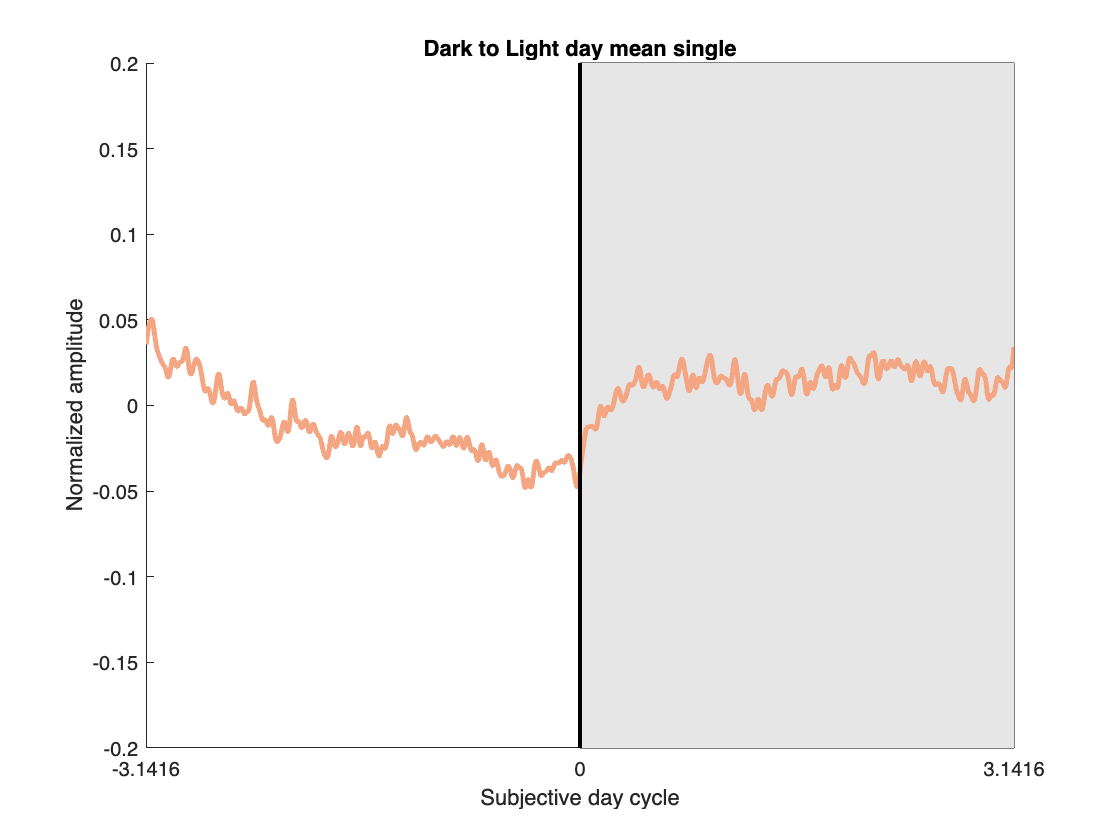

figure(317); clf; title('Dark to Light day mean single'); hold on; 
    
   set(gca,'XTick',-2*pi:pi:2*pi);
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    ylim([-0.2 0.2]);
    xlim([-pi pi]);
   % xlim([-.5 .5]);
    a = ylim;
clrs = k_colormefriendly;

    fill([0 0 pi pi], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');

    for j = 7%length(light):-1:1
   
        testmean = mean(meanday);
        ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * light(j).ld); 
        plot((light(j).exp.hourtim .* crosshour)-pi, testmean-mean(testmean), 'LineWidth', 2.5,'Color', clrs(j,:),'DisplayName',num2str(ld(j)));
        
        % legend(num2str(ld(j))); 
       % legend('AutoUpdate', 'off'); 
     %  legend;
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Normalized amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');

# multifish

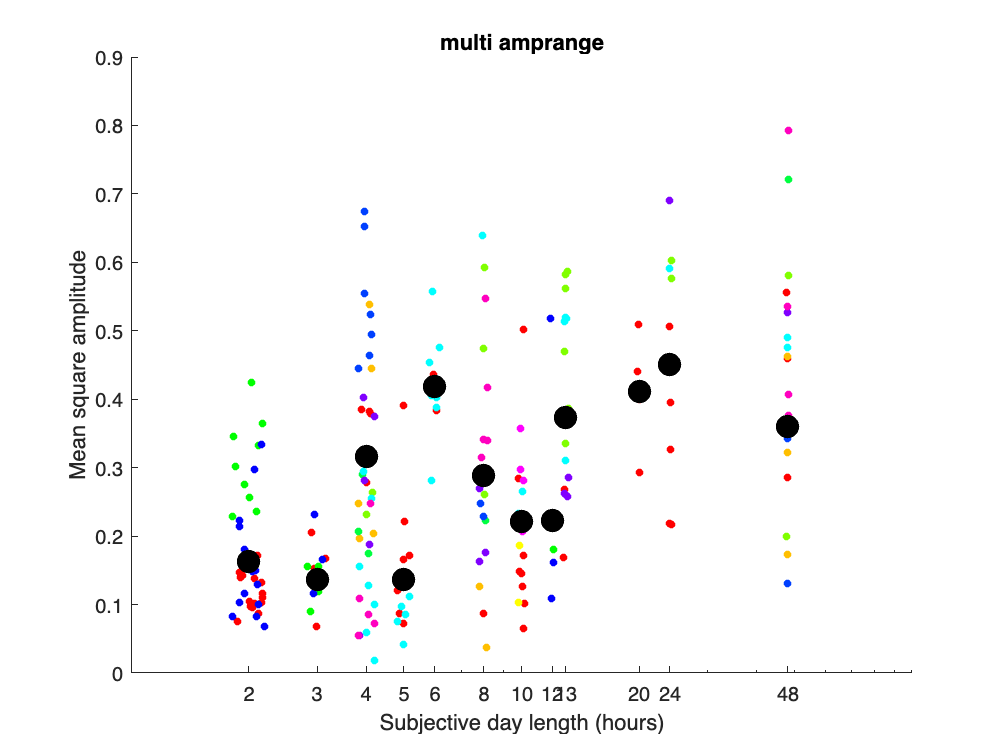

figure(98); clf; title('multi amprange'); hold on;
 set(gcf, 'Renderer', 'painters');
 ylim([0 .9]);
    for j = 1:length(darkmulti)

        ld(j,:) = darkmulti(j).ld;
       
        for kk = 1:length([darkmulti(j).fish])
            clrbyfish = hsv(length(darkmulti(j).fish));
            for jj = 1:length(darkmulti(j).fish(kk).amprange)
            %plot(ld(j,:), dark(j).fish(kk).amprange(jj), '.', 'MarkerSize', 8);
            scatter(ld(j,:), darkmulti(j).fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
            end
        end
       
        plot(ld(j,:), darkmulti(j).exp.expavgrange, 'k.', 'MarkerSize', 35);

    end
    set(gca,'xscale', 'log');%, 'yscale', 'log');
   xticks([2 3 4 5 6 8 10 12 13 20 24 48]);
   xlabel('Subjective day length (hours)');
   ylabel('Mean square amplitude');

dark to light

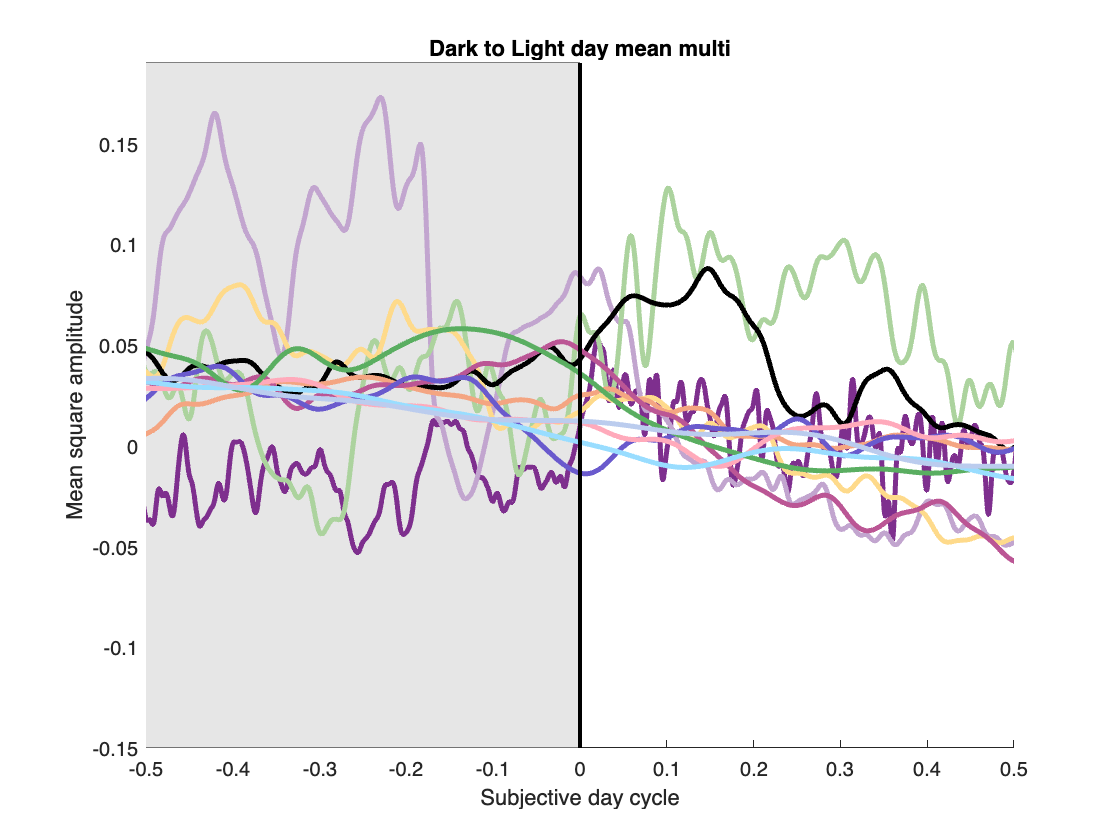

figure(316); clf; title('Dark to Light day mean multi'); hold on; 
 set(gcf, 'Renderer', 'painters');

   set(gca,'XTick',-2*pi:pi:2*pi)
   ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
  ylim([-0.15 0.19]);
    xlim([-pi pi]);
   % xlim([-.5 .5]);
    a = ylim;
clrs = k_colormefriendly;

  fill([-pi -pi 0 0], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
    for j = length(darkmulti):-1:1
   
        ld(j,:) = darkmulti(j).ld;
        crosshour = (2*pi) / (2 * darkmulti(j).ld);
        p(j) = plot((darkmulti(j).exp.hourtim .* crosshour)-pi, darkmulti(j).exp.meanofexperimentmeans-mean(darkmulti(j).exp.meanofexperimentmeans), 'LineWidth', 2.5,'Color', clrs(j,:));
        
%          legend(num2str(ld) + ':' + num2str(ld)); 
%         legend('AutoUpdate', 'off'); 
%     
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');

## light to dark

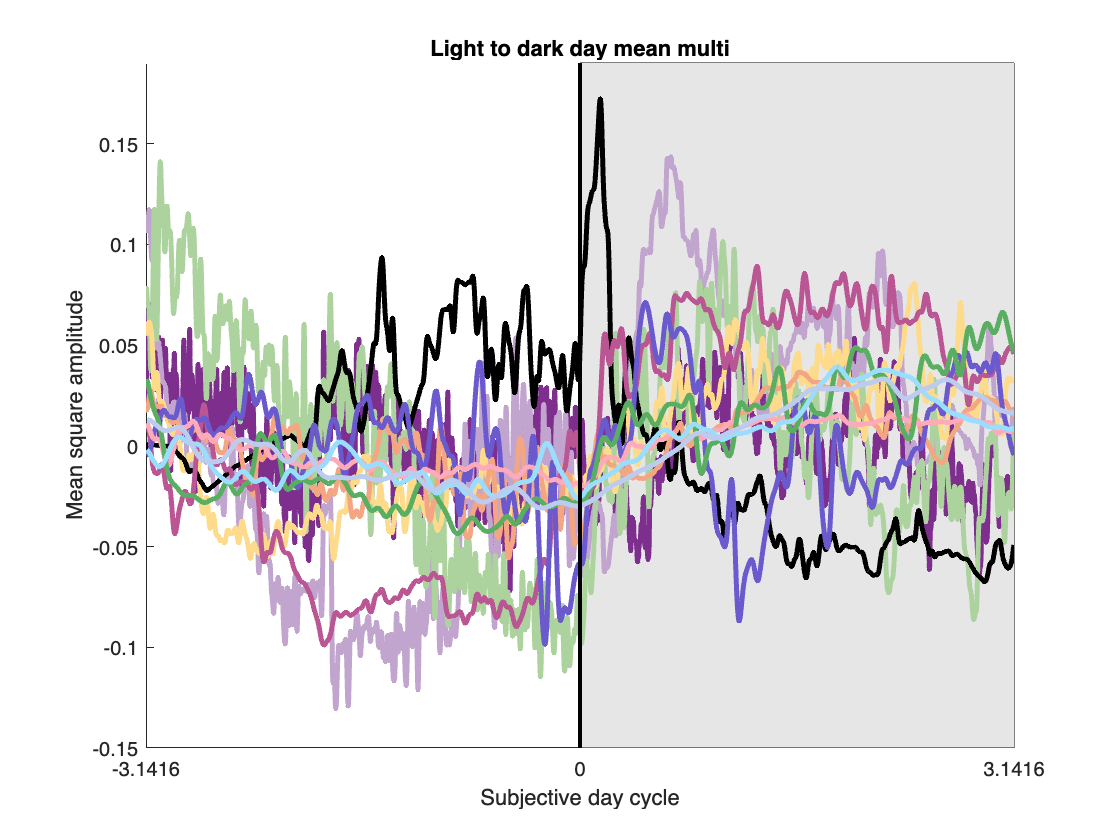

figure(316); clf; title('Light to dark day mean multi'); hold on; 
 set(gcf, 'Renderer', 'painters');

%   set(gca,'XTick',-2*pi:pi:2*pi)
 %  ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
  ylim([-0.15 0.19]);
 %   xlim([-pi pi]);
    xlim([-.5 .5]);
    a = ylim;
clrs = k_colormefriendly;

  fill([0 0 pi pi], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
    for j = length(lightmulti):-1:1
   
        ld(j,:) = lightmulti(j).ld;
        crosshour = (2*pi) / (2 * lightmulti(j).ld);
        p(j) = plot((lightmulti(j).exp.hourtim .* crosshour)-pi, lightmulti(j).exp.meanofexperimentmeans-mean(lightmulti(j).exp.meanofexperimentmeans), 'LineWidth', 2.5,'Color', clrs(j,:));
        
%          legend(num2str(ld) + ':' + num2str(ld)); 
%         legend('AutoUpdate', 'off'); 
%     
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');

# Boostrap test for n smoothing

# single fish - multi will be the same

Average amplitude range figure

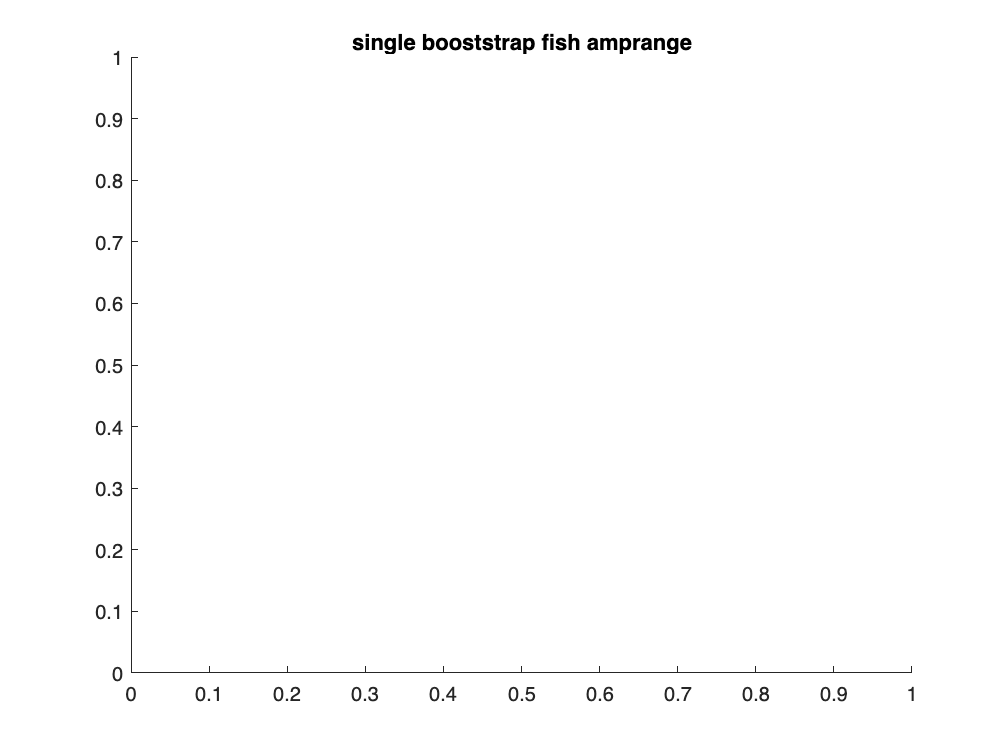

figure(878); clf; title('single booststrap fish amprange'); hold on;


    for j = 1:length(darker)%loop through experiment hours

        ld(j,:) = darker(j).ld;

        fish = unique(darker(j).singlefish.fish');
        clrbyfish = hsv(length(fish));
  
            
            for jj = 1:length(darker(j).singlefish.singlesomeamprange)
                    clridx(jj) = find(darker(j).singlefish.fish(jj) == fish);
                 scatter(ld(j,:), darker(j).singlefish.singlesomeamprange(jj), 15, clrbyfish(clridx(jj),:),'filled','jitter', 'on', 'jitterAmount', 0.2);

            end
       
        plot(ld(j,:), darker(j).singexp.expavgrange, 'k.', 'MarkerSize', 35);

    end

Unrecognized function or variable 'darker'.

   set(gca,'xscale', 'log');%, 'yscale', 'log');
   xticks([2 3 4 5 6 8 10 12 13 20 24 48]);
   xlabel('Subjective day length (hours)');
   ylabel('Mean square amplitude');

Daymean average

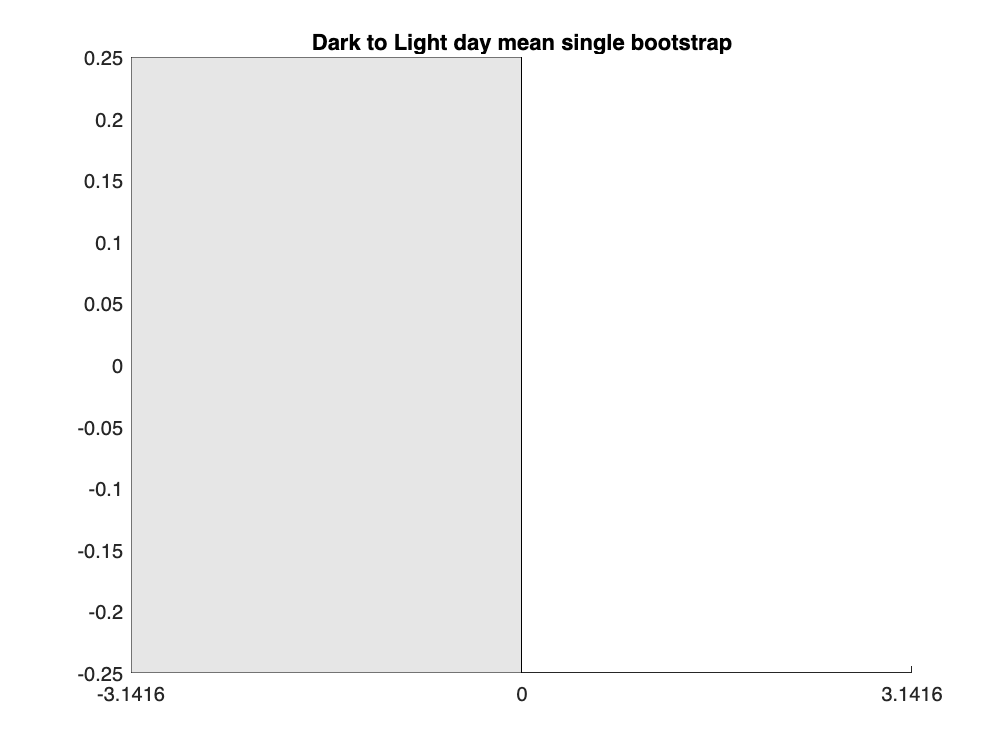

figure(317); clf; title('Dark to Light day mean single bootstrap'); hold on; 
    set(gcf, 'Renderer', 'painters');
    set(gca,'XTick',-2*pi:pi:2*pi);
   % ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    ylim([-0.25 0.25]);
    xlim([-pi pi]);
    a = ylim;
clrs = k_colormefriendly;

    fill([-pi -pi 0 0], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');


    for j = 1:length(darker)
   
        ld(j,:) = darker(j).ld;
        crosshour = (2*pi) / (2 * darker(j).ld);
        p(j) = plot((darker(j).singexp.hourtim .* crosshour)-pi, darker(j).singexp.meanofexperimentmeans, 'LineWidth', 2.5,'Color', clrs(j,:));
        
         legend(num2str(ld)); 
        legend('AutoUpdate', 'off'); 
    
    end

Unrecognized function or variable 'darker'.

       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');